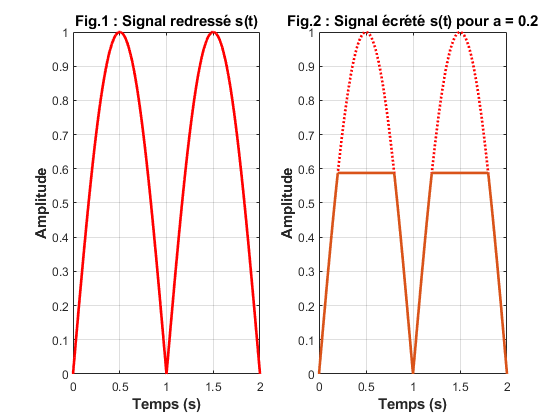

clear; clc; clf; close all;

T=1;    %periode
F=1/T;
Fm=1;
NbHarm=20; %nombre de'harmonique
dt=0.001; %le pas
a=0.2; 

% Calcul de s(t)
% --------------
[sr,t] = signal_P1718(T, 0.5, dt); % Signal dent de scie
[s,t] = signal_P1718(T, a, dt); % Signal tronqué
%

figure;

subplot(1,2,1);
plot(t,sr,'r','linewidth',2);
grid;
title('\fontsize{11}\bfFig.1 : Signal redressé s(t)');
xlabel('\fontsize{11}\bfTemps (s)');
ylabel('\fontsize{11}\bfAmplitude');

subplot(1,2,2);
plot(t,sr,':r',t,s,'linewidth',2);
grid;
title(['\fontsize{11}\bfFig.2 : Signal écrété s(t) pour a = ',num2str(a)]);
xlabel('\fontsize{11}\bfTemps (s)');
ylabel('\fontsize{11}\bfAmplitude');






SignalR=mean(s); % Valeur moyenne du signal
Text=['La valeur moyenne sm de s(t) est ',num2str(SignalR)];
disp(Text)

La valeur moyenne sm de s(t) est 0.47378




Text=['La Pm de s(t) est ',num2str((SignalR)^2)];
disp(Text)

La Pm de s(t) est 0.22447


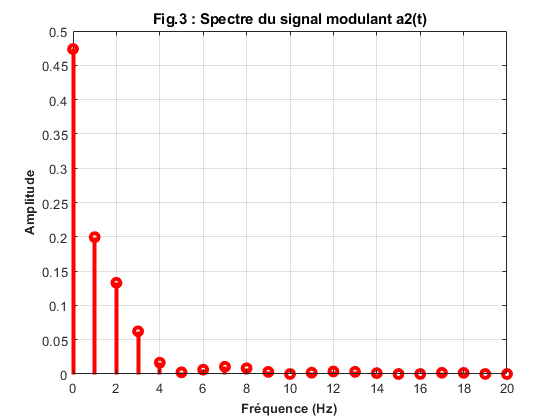

% Spectre en amplitude du signal

C0=mean(s);

for k=1:NbHarm
    X(k)=mean(s.*exp(-2*pi*1i*k*Fm*t));
    C(k)=abs(2*X(k));
    Phi(k)=angle(X(k));
    if C(k)<0.001
        C(k)=0;
    end
end
% Tracé du spectre en amplitude du signal s(t)
k=1:NbHarm;
figure(3);
stem(0,C0,'r','LineWidth',3);grid;hold on;
stem(k,C,'r','LineWidth',3);hold off;
title('Fig.3 : Spectre du signal modulant a2(t)')
xlabel('\fontsize{10}\bfFréquence (Hz)')
ylabel('\fontsize{10}\bfAmplitude')

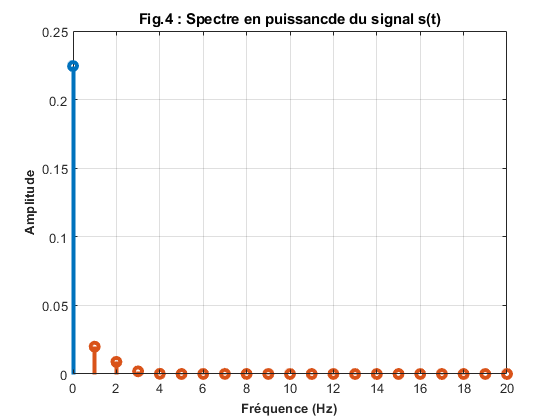


Pm=(C0)^2;
for k=1:NbHarm
    Ph(k)=0.5*C(k)^2;
end

k=1:NbHarm;
figure(4);
stem(0,Pm,'LineWidth',3);grid on; hold on;
stem(k,Ph,'LineWidth',3);grid on;hold off;
title('Fig.4 : Spectre en puissancde du signal s(t)')
xlabel('\fontsize{10}\bfFréquence (Hz)');
ylabel('\fontsize{10}\bfAmplitude')

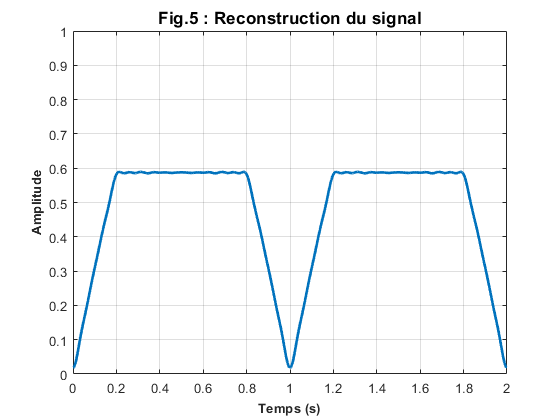



% Reconstitution du signal
Som=zeros(1,length(t));
for k=1:NbHarm
    Harmo=C(k).*cos(2*pi*k*Fm*t+Phi(k)); 
    Som=Som+Harmo;
end

plot(t,Som+C0,'linewidth',2);grid; %Som + C0 pour prendre en compte le premiere harmonique qui n'est pas inclu dans C
title('\fontsize{13}\bfFig.5 : Reconstruction du signal')
xlabel('\fontsize{10}\bfTemps (s)');
ylabel('\fontsize{10}\bfAmplitude')
xlim([0 2])
ylim([0 1])





%Parseval 



    0.2010



trapz(t,s)

ans = 0.9485

sum(C)+C0       %Pareil ????

ans = 0.9292